# おまけ：YAMNet用メルスペクトログラムの自動生成を用いた特徴抽出と転移学習による異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

YAMNetによる異音判定の例題は以下をご参照ください。

[https://jp.mathworks.com/help/audio/ref/yamnet.html](https://jp.mathworks.com/help/audio/ref/yamnet.html)

YAMNet用にメルスペクトログラムを求める前処理（関数yamnetPreprocess）は以下のページをご参照ください。

[https://jp.mathworks.com/help/audio/ref/yamnetpreprocess.html](https://jp.mathworks.com/help/audio/ref/yamnetpreprocess.html)

関数yamnetPreprocessを使用することで非常にシンプルにコードを記載することが可能です。

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Deep Learning Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

url = 'https://www.mathworks.com/supportfiles/audio/AirCompressorDataset/AirCompressorDataset.zip';
downloadFolder = fullfile(tempdir,'aircompressordataset');
datasetLocation = tempdir;

if ~exist(fullfile(tempdir,'AirCompressorDataSet'),'dir')
    loc = websave(downloadFolder,url);
    unzip(loc,fullfile(tempdir,'AirCompressorDataSet'))
end

ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads);
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

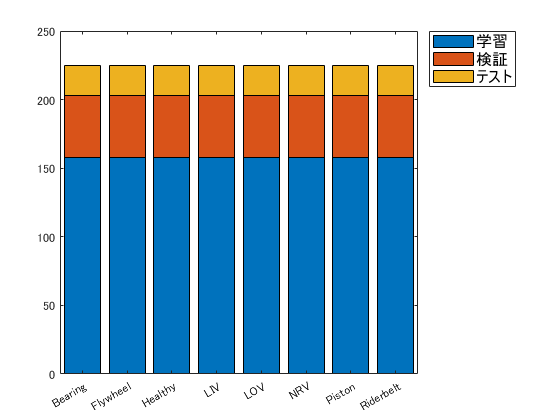

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## 可視化

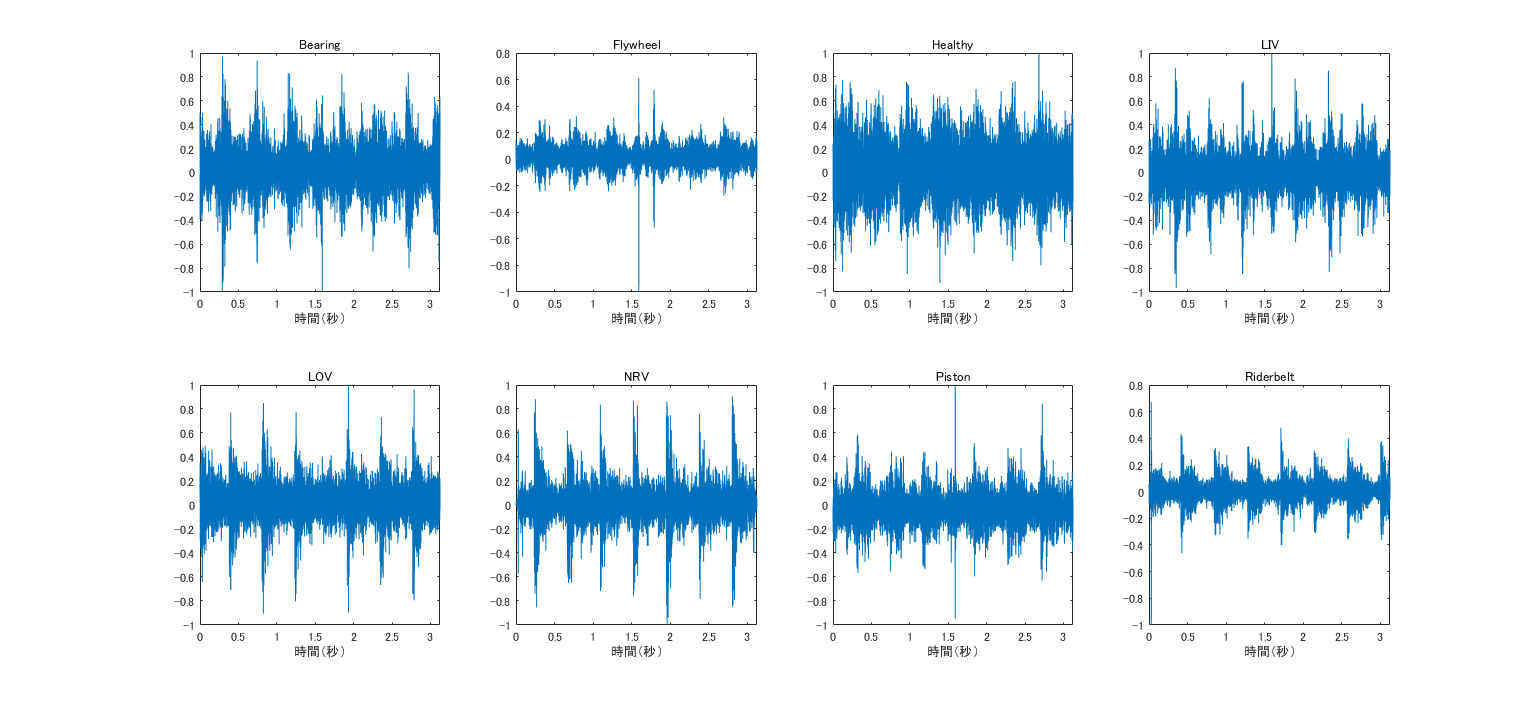

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## 学習用

trainFeatures = [];
trainLabels = adsTrain.Labels;
reset(adsTrain);
tic
while hasdata(adsTrain)
    [audioIn,fileInfo] = read(adsTrain);
    melSpectYam = yamnetPreprocess(audioIn,fs);
    trainFeatures = cat(4,trainFeatures,melSpectYam(:,:,1,1));
end
toc

経過時間は 17.519325 秒です。


## 検証用

validationFeatures = [];
validationLabels = adsValidation.Labels;
reset(adsValidation);
tic
while hasdata(adsValidation)
    [audioIn,fileInfo] = read(adsValidation);
    melSpectYam = yamnetPreprocess(audioIn,fs);
    validationFeatures = cat(4,validationFeatures,melSpectYam(:,:,1,1));
end
toc

経過時間は 3.526363 秒です。


## テスト用

testFeatures = [];
testLabels = adsTest.Labels;
reset(adsTest);
tic
while hasdata(adsTest)
    [audioIn,fileInfo] = read(adsTest);
    melSpectYam = yamnetPreprocess(audioIn,fs);
    testFeatures = cat(4,testFeatures,melSpectYam(:,:,1,1));
end
toc

経過時間は 1.603198 秒です。


## 学習済みネットワーク YAMNet の読み込み

downloadFolder = fullfile(tempdir,'YAMNetDownload');
loc = websave(downloadFolder,'https://ssd.mathworks.com/supportfiles/audio/yamnet.zip');
YAMNetLocation = tempdir;
unzip(loc,YAMNetLocation)
addpath(fullfile(YAMNetLocation,'yamnet'))

## 出力層の変更

uniqueLabels = unique(adsTrain.Labels);
numLabels = numel(uniqueLabels);

net = yamnet;

lgraph = layerGraph(net.Layers);

newDenseLayer = fullyConnectedLayer(numLabels,"Name","dense");
lgraph = replaceLayer(lgraph,"dense",newDenseLayer); %* 全結合層を8クラスに付け替え

newClassificationLayer = classificationLayer("Name","Sounds","Classes",uniqueLabels);
lgraph = replaceLayer(lgraph,"Sound",newClassificationLayer); %* 出力層も再定義

## 学習のオプション

miniBatchSize = 128;
validationFrequency = floor(numel(trainLabels)/miniBatchSize);

options = trainingOptions('adam', ...
    'InitialLearnRate',3e-4, ...
    'MaxEpochs',5, ...
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationData',{single(validationFeatures),validationLabels}, ...
    'ValidationFrequency',validationFrequency);

## 学習の開始

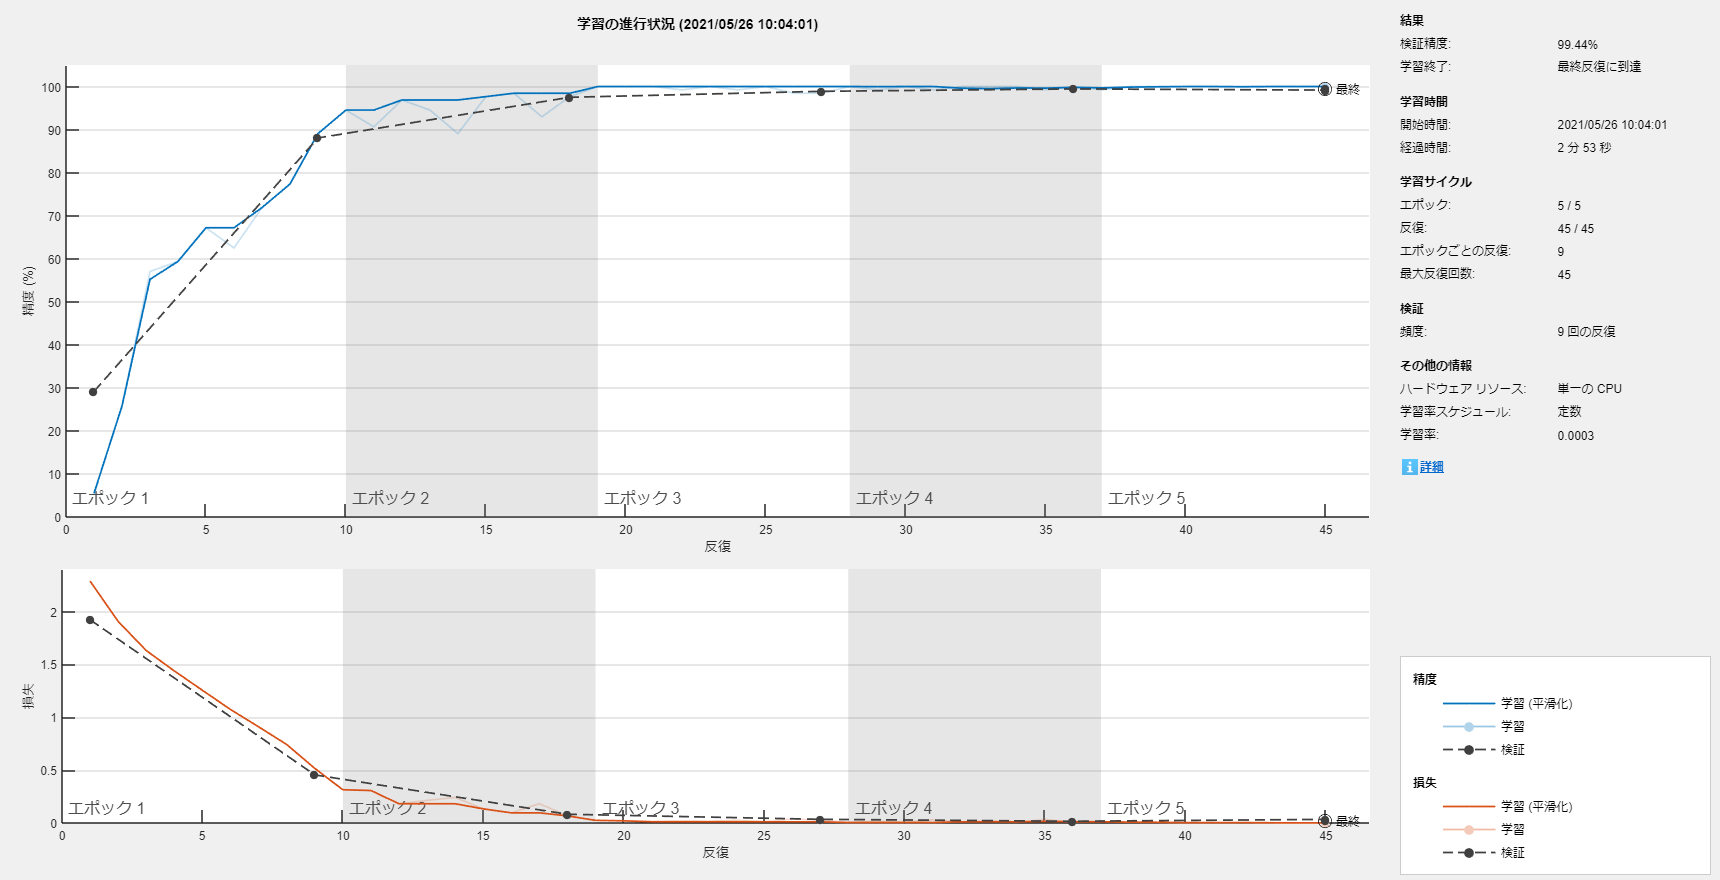

trainedNet = trainNetwork(single(trainFeatures),trainLabels,lgraph,options);

## テスト：精度検証

tblTest

tblTest = 8×2 table
      Label      Count
    _________    _____
    Bearing       22  
    Flywheel      22  
    Healthy       22  
    LIV           22  
    LOV           22  
    NRV           22  
    Piston        22  
    Riderbelt     22  

predLabels = classify(trainedNet,single(testFeatures));
accuracy = 100*sum(predLabels == testLabels) / numel(testLabels) % 精度（%）

accuracy = 98.8636

## 混同行列

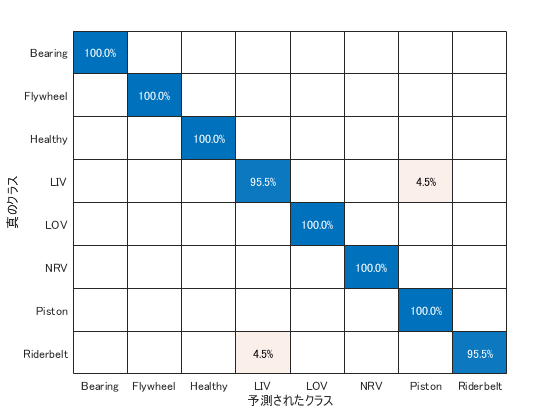

figure; clf;
confusionchart(testLabels, predLabels,"Normalization","row-normalized")

## 精度の可視化

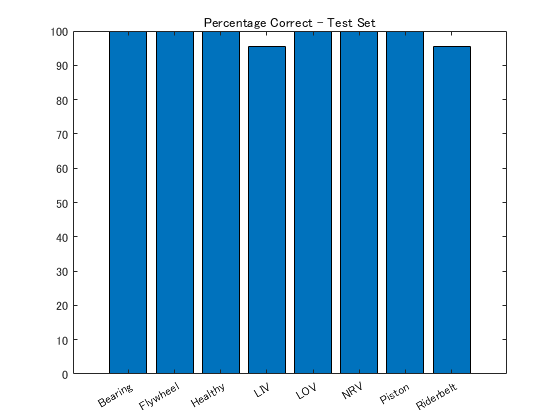

cm = confusionmat(testLabels, predLabels);
genreAccuracy = diag(cm)./tblTest.Count*100;
figure; clf;
bar(genreAccuracy)
set(gca,'XTickLabels',uniqueLabels);
xtickangle(gca,30);
title('Percentage Correct - Test Set');

*Copyright 2021 The MathWorks, Inc.*